## In the name of Allah

## Project 5:

## Hossein Alizadeh Piralidehi 810100522

### Problem considerations:

we are given N iid samples from mixture density:


$$p\left(x;\lambda \right)=\sum_{j=1}^k \lambda_j p_j \left(x\right)$$


where $\lambda_j$ is mixture coefficients and $\lambda \in R_+^k \;\;,1^T \lambda =1$

and $p_i \left(x\right)$ are given densities on $R^m$

we find ML estimate of $\lambda$ using convex optimization.

### Description:

here we try to calculate Likelihood and formulate problem as convex optimization problem:


$$\begin{array}{l}
p\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_N ;\lambda \right)=\prod_{i=1}^N p\left(x_i ;\lambda \right)=\prod_{i=1}^N \sum_{j=1}^k \lambda_j p_j \left(x_i \right)\\
\ell =\log \left(p\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_N ;\lambda \right)\right)=\sum_{i=1}^N \log \left(\sum_{j=1}^k \lambda_j p_j \left(x_i \right)\right)
\end{array}$$


now considering probability densities $p_i \left(x\right)$ are known we can rewrite log-likelihood:


$$\begin{array}{l}
{c_i }^T \lambda =\left(\sum_{j=1}^k \lambda_j p_j \left(x_i \right)\right)\;\;\;\;\;\mathrm{which}\;\mathrm{jth}\;\mathrm{element}\;\mathrm{of}\;c_i \;\;\mathrm{is}:p_j \left(x_i \right)\\
\ell =\log \left(p\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_N ;\lambda \right)\right)=\sum_{i=1}^N \log \left(c_i^T \lambda \right)
\end{array}$$


$c_i^T \lambda$ is affine in $\lambda$, and $\log \left(x\right)$ is concave function so $\log \left(c_i^T \lambda \right)$ which is combination of concave and affine will be concave, as we know summation will preserve concavity so log-likelihood function is concave in $\lambda$.

finally optimization problem can be described as below:


$$\begin{array}{l}
\max \;\sum_{i=1}^N \log \left(c_i^T \lambda \right)\\
\;\;\;\;s\ldotp t\ldotp \\
\;\;\;\;\;\;\;\;1^T \lambda =1\\
\;\;\;\;\;\;\;\;\;\lambda \ge 0
\end{array}$$


which is an convex optimization problem with affine constraints.

### Simulation with given parameters:

## Part a)

load parameters

clc;clear;close all;

lambdas_true = [0.3; 0.5; 0.2];
load('mixture_coeffs_data.mat');

C = densities;

solve convex problem using cvx toolbox

cvx_begin
    variables lambdas(size(densities,2));
    ML_Objective = 0;
    for i = 1 : size(densities,1)
        ML_Objective = ML_Objective + log(C(i,:)*lambdas);
    end
    maximize( ML_Objective );
    subject to
        ones(1,size(densities, 2))*lambdas == 1;
        lambdas >= 0;
cvx_end

 
Successive approximation method to be employed.
   For improved efficiency, SDPT3 is solving the dual problem.
   SDPT3 will be called several times to refine the solution.
   Original size: 304 variables, 103 equality constraints
   100 exponentials add 800 variables, 500 equality constraints
-----------------------------------------------------------------
 Cones  |             Errors              |
Mov/Act | Centering  Exp cone   Poly cone | Status
--------+---------------------------------+---------
100/100 | 8.000e+00  4.548e+00  0.000e+00 | Solved
100/100 | 2.152e+00  3.041e-01  0.000e+00 | Solved
100/100 | 1.046e-01  7.037e-04  0.000e+00 | Solved
100/100 | 1.679e-02  1.774e-05  0.000e+00 | Solved
100/100 | 2.234e-03  3.137e-07  0.000e+00 | Solved
  0/100 | 3.012e-04  5.504e-09  0.000e+00 | Solved
-----------------------------------------------------------------
Status: Solved
Optimal value (cvx_optval): -206.882
 


## plot outputs

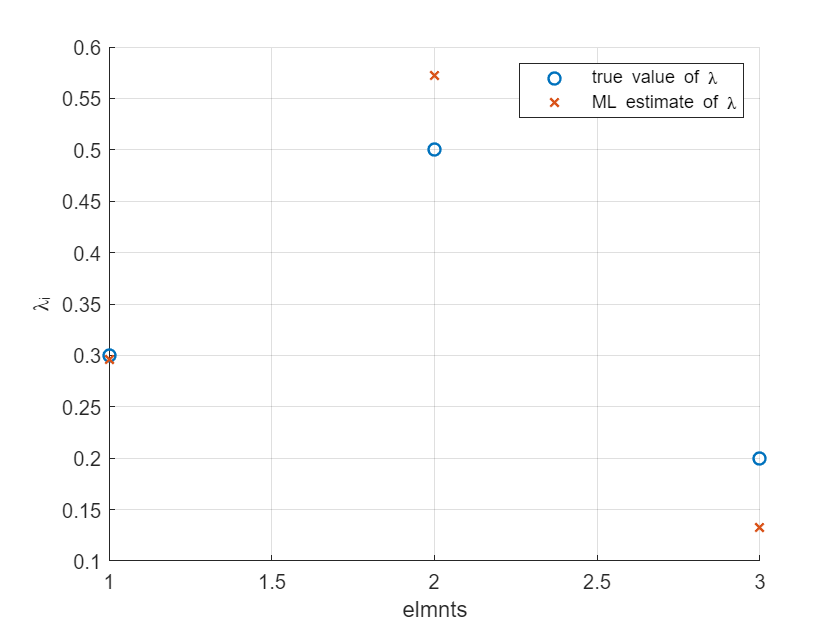

figure
hold on
grid on
plot(lambdas_true,'o','LineWidth',1.2)
plot(lambdas, 'x','LineWidth',1.2)
xlabel('elmnts')
ylabel('\lambda_i')
legend('true value of \lambda', 'ML estimate of \lambda')

as we see for N = 100 samples of mixture density, ML estimate of lambdas are close to true value of them. and by increasing number of samples this estimation will be more accurate and converge to true value of lambdas.